imagePath = "testResult\";
fileName = dir("testResult\*.txt");
N = length(fileName);
fileName = struct2table(fileName); fileName = table2cell(fileName(:,1));
fileName = natsortfiles(fileName);
data = load(imagePath + fileName{1});
[m,n] = size(data); 
Alldata = zeros(m,n,N);
for i = 1:N
    Alldata(:,:,i) = load(imagePath + fileName{i});
end

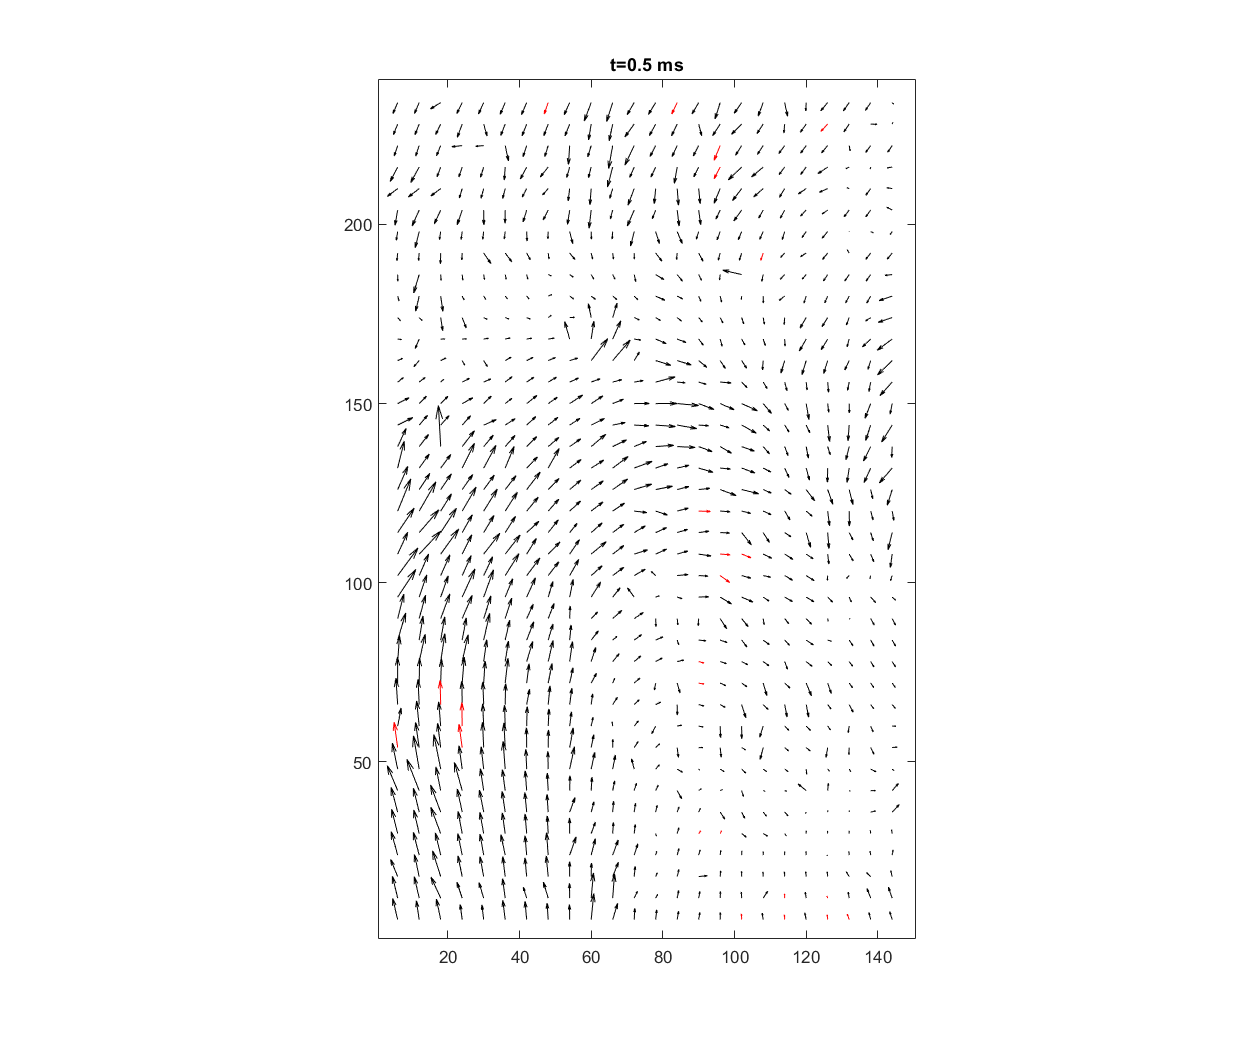

i = 1

clear F;
step = 1;
for i = 1:1
    a = figure(1);
    clf;
    data = Alldata(:,:,i);
    % read data and reshape to 2D matrix from original format
    X = reshape(data(1:step:end,1), 24, [])';
    Y = reshape(data(1:step:end,2), 24, [])';
    U = reshape(data(1:step:end,3), 24, [])';
    V = reshape(data(1:step:end,4), 24, [])';
    %remove the outlier
    
    uOut = isoutlier(U,'gesd'); uOutI = find(uOut);
    vOut = isoutlier(V,'gesd'); vOutI = find(vOut);
    Out = uOut + vOut; Out(Out>0) = 1; OutI = find(Out);
    x = (reshape(X,1,[])'); xOut = x(OutI); 
    y = (reshape(Y,1,[])'); yOut = y(OutI); 
    U(Out == 1) = nan; V(Out == 1) = nan;
    %U = U.*(1-uOut); V = V.*(1-vOut); U(U==0 || V==0) = nan; V(V==0 || U ==0) = nan;
    u = fillmissing(U,'movmedian',5); v = fillmissing(V,'movmedian',5);
    u(Out ~= 1) = nan; v(Out ~= 1) = nan;
    %u = filloutliers(U,'next','gesd');
    %v = filloutliers(V,'next','gesd');
    quiver(X,Y,U,V,'k','AutoScale',"off");
    hold on;
    quiver(X,Y,u,v,'r','AutoScale',"off");
%     hold on;
%     scatter(xOut,yOut,500,'r.');
    hold off;
    title(['t=', num2str(i/2000*1000), ' ms'])
    axis equal
    set(gcf,'position',[10,10,1000,1000])
    axis([0 150 0 240]); 
    F(i) = getframe(a);
    i
end

writerObj = VideoWriter('velocityHighSpeed.avi');
writerObj.FrameRate = 3;
open(writerObj);
for i = 1:200
    writeVideo(writerObj, F(i));
end
close(writerObj);

usp = squeeze(Alldata(770,4,:));
figure(3)
xplot = 0.5:0.5:1000

xplot = 	1.0e+03 *

    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245    0.0250


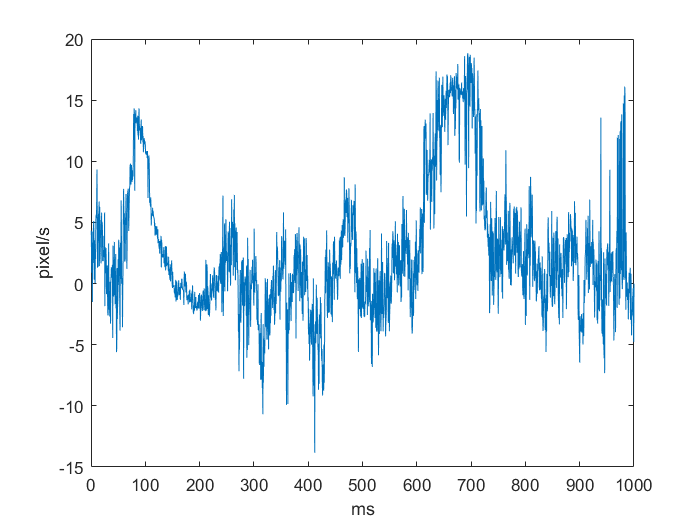

plot(xplot,usp(2001:4000))
xlabel('ms')
ylabel('pixel/s')

usp = usp - mean(usp);
usp = reshape(usp, 1, []);
[freq, P] = leo_spectra_detailed(usp(1:22000)',1,2000,7)

freq =          0    0.0909    0.1818    0.2727    0.3636    0.4545    0.5455    0.6364    0.7273    0.8182    0.9091    1.0000    1.0909    1.1818    1.2727    1.3636    1.4545    1.5455    1.6364    1.7273    1.8182    1.9091    2.0000    2.0909    2.1818    2.2727    2.3636    2.4545    2.5455    2.6364    2.7273    2.8182    2.9091    3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545


P =     0.0000
    3.6128
    2.3454
    1.8022
    1.8175
    0.3737
    0.3736
    0.8413
    1.1828
    1.4298


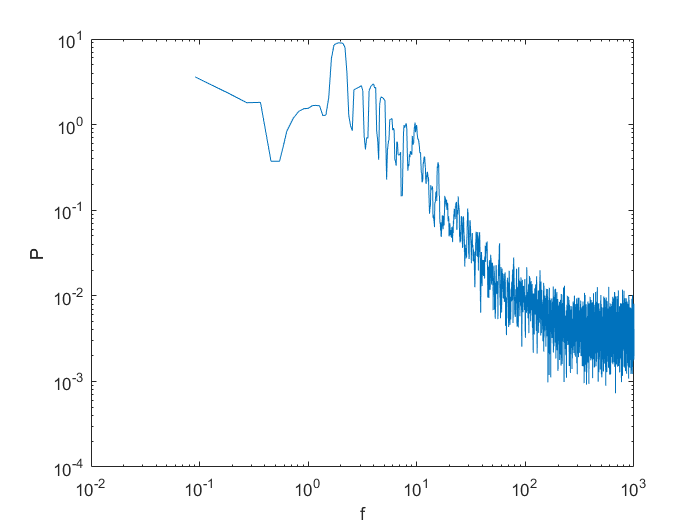

figure(2)
loglog(freq,P)
xlabel('f')
ylabel('P')

dataMean = mean(Alldata,3)
figure(2)
subplot(3,2,1)
quiver(dataMean(:,1),dataMean(:,2),dataMean(:,3),dataMean(:,4),4,'k');
axis([0 2100 0 2100]);
subplot(3,2,2)
histogram(dataMean(:,3))
title('mean u velocity (pixel/s)')
subplot(3,2,3)
histogram(dataMean(:,4))
title('mean v velocity (pixel/s)')
subplot(3,2,4)
Uall = Alldata(:,3,:);
histogram(Uall(:));
title('all frame u velocity (pixel/s)');
subplot(3,2,5)
Vall = Alldata(:,4,:);
histogram(Vall(:));
title('all frame v velocity (pixel/s)');

clear result;
l = round(1/1.28127 * 8 * 90);
%l = 200;
[M,N,T] = size(Alldata)
result = zeros(M,N,T - l);
for (i = 1:T-l)
    result(:,:,i) = mean(Alldata(:,:,i:i+l-1),3);
end

clear F_new;
count = 1;
for i = 1:T-l
    a = figure(5);
    data = result(:,:,i);
    X = data(:,1);
    Y = data(:,2);
    U = data(:,3);
    V = data(:,4);
    quiver(X,Y,U,V,2,'k');
    axis([0 2100 0 2100]);
    set(gcf,'position',[10,10,1000,1000])
    F_new(count) = getframe(a);
    count = count + 1;
end

writerObj = VideoWriter('muscle90fps3kfpstopright_Average8cycles.avi');
writerObj.FrameRate = 10;
open(writerObj);
for i = 1:length(F_new)
    writeVideo(writerObj, F_new(i));
end
close(writerObj);

% steamline plot 
clear F_stream;
count = 1;
for i = 1:T-l
    a = figure(3);
    clf(a);
    data = result(:,:,i);
    X = reshape(data(:,1),135,135)';
    Y = reshape(data(:,2),135,135)';
    U = reshape(data(:,3),135,135)';
    V = reshape(data(:,4),135,135)';
    xstart = max(X, [], 'all')*rand(200,1); 
    ystart = max(Y, [], 'all')*rand(200,1); 
%     startx = X(1,:);
%     starty = 2025 * ones(size(startx));
    %starty1 = 1400 * ones(size(startx));
    streamline(X,Y,U,V,xstart,ystart);
    %streamline(X,Y,U,V,startx,starty1);
    axis([0 2100 0 2100]);
    set(gcf,'position',[10,10,1000,1000])
    F_stream(count) = getframe(a);
    count = count + 1;
    %clf(a);
    count
end

writerObj = VideoWriter('muscle90fps3kfpstopright_streamline8cycles.avi');
writerObj.FrameRate = 10;
open(writerObj);
for i = 1:length(F_stream)
    writeVideo(writerObj, F_stream(i));
end
close(writerObj);


